syms mu real
N = 5;

Diffúziós mátrix alakja:

A_N(mu,N)

$$ans = \left(\begin{array}{ccccc} 1-\mu & \mu & 0 & 0 & 0\\ \mu & 1-2\,\mu & \mu & 0 & 0\\ 0 & \mu & 1-2\,\mu & \mu & 0\\ 0 & 0 & \mu & 1-2\,\mu & \mu \\ 0 & 0 & 0 & \mu & 1-\mu \end{array}\right)$$

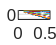

N = 10;

mu = linspace(0.1,0.6,1000);
Eigs = zeros(N,numel(mu));
for i = 1:numel(mu)
    Eigs(:,i) = eig(A_N(mu(i),N));
end

plot(mu,Eigs')
grid on

function A = A_N(mu,N)
    elso_sor = [1-2*mu mu zeros(1,N-2)];
    A = toeplitz(elso_sor,elso_sor);
    A(1) = 1 - mu;
    A(end) = 1 - mu;
end



